# **Ejemplo -** Método de Hardy-Cross

Problema tomado del ejemplo 12.10 de *V. L. Streeter, E. B. Wylie y K. W. Bedford, Mecánica de Fluidos, 9 ed.*

El método Hardy-Cross es una técnica iterativa utilizada para determinar los flujos en una red de tuberías cerrada. Consiste en asumir valores iniciales de flujo, calcular las pérdidas de carga y corregir sucesivamente los flujos hasta alcanzar una condición de equilibrio hidráulico.

En el problema planteado debajo, se desea conocer la distribución de caudales a través de la red de la figura mostrada para los caudales de entrada y salida dados en cada nodo.

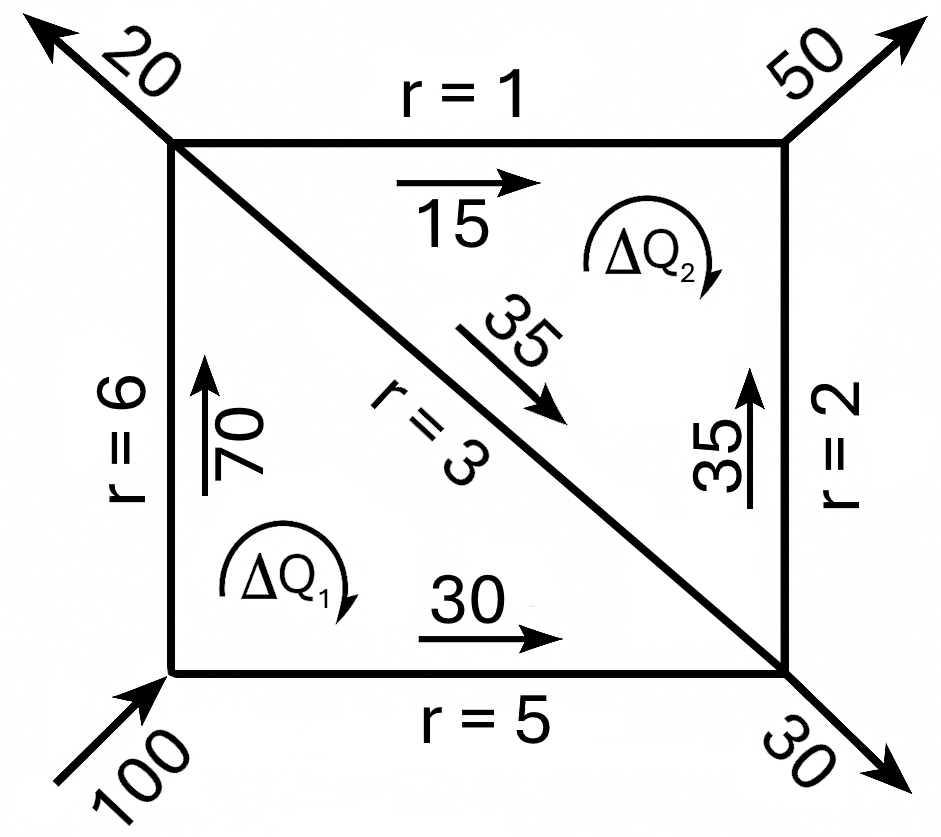

## Datos conocidos/asumidos

Q = [15;35;30;70;35];   % Flujos iniciales asumidos (m³/h) [deben cumplir la continuidad]
r = [1;2;5;6;3];        % Coeficientes de resistencia
n = 2;                  % Exponente en ecuación de pérdidas

tol = 1e-2;             % Tolerancia de convergencia (m³/h)
maxIter = 20;           % Iteraciones máximas

% Definición de mallas (ciclos o circuito elemental)
loops = { [1 2 5], [5 3 4] };       % Índices de tuberías para las mallas
signs = { [ 1 -1 -1], [ 1 -1  1] }; % Signos para dirección del flujo

% Inicialización del gráfico
corrs = zeros(2,maxIter);  % dQ de cada malla/iteración
figure(1), clf, hold on
xlabel("Iteración"), ylabel("Corrección de caudal, dQ (m³/h)"), grid on


## Proceso iterativo

Para cada tubería en cada malla, se calcula la pérdida hidráulica, hf. En cada malla se calcula una corrección de caudal, dQ, que se suma sucesivamente con cada iteración hasta llegar a la convergencia.

$h_f =r\cdot Q\cdot {\left|Q\right|}^{n-1}$;        $\Delta Q=-\frac{\sum h_f }{\sum r\cdot n\cdot {\left|Q\right|}^{n-1} }$

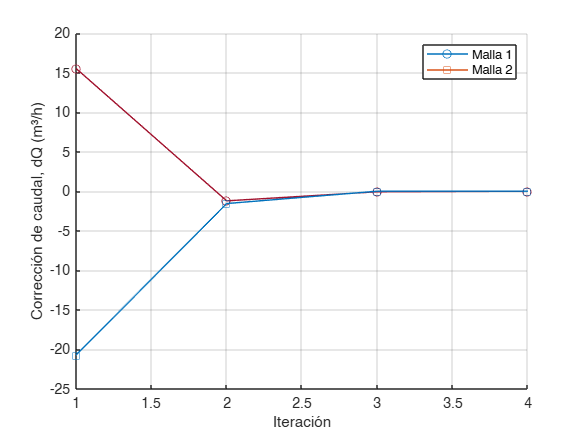

for k=1:maxIter
    dQ = zeros(2,1);

    for L=1:2 % En cada malla
        idx = loops{L}; s = signs{L}; Qi = Q(idx);

        % Pérdidas hidráulicas
        H = s'.*r(idx).*Qi.^(n-1).*abs(Qi);

        % dH/dQ = n * r_i * |Q_i|^(n-1)
        dH = n*r(idx).*abs(Qi).^(n-1);

        % Corrección de caudal de la malla
        dQ(L) = -sum(H)/sum(dH);

        % Caudales corregidos en cada tubería
        Q(idx) = Q(idx)+s'*dQ(L);

    end
    corrs(:,k) = dQ;

    % Actualizar gráfica
    plot(1:k, corrs(1,1:k),'-o'); plot(1:k, corrs(2,1:k),'-s');

    if max(abs(dQ))<tol
        break
    end
end
legend('Malla 1','Malla 2')

## Resultados obtenidos

% Flujos en cada tubería
T = table((1:5)', Q, 'VariableNames',{'Tubería','Flujo_m³/h'}); disp(T)

    Tubería    Flujo_m³/h
    _______    __________

       1         29.241  
       2         20.759  
       3         52.271  
       4         47.729  
       5         -1.512  



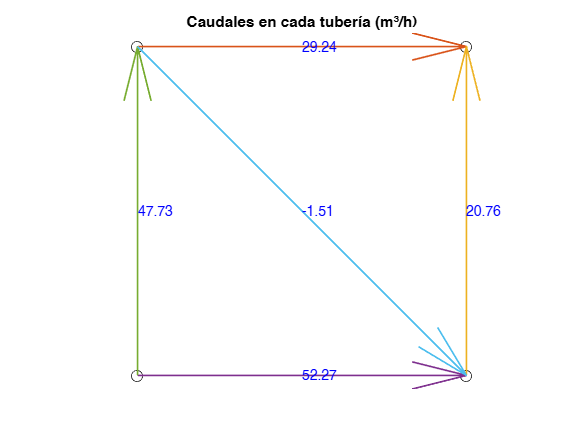


% Gráfico de la red con sus flujos
nodes = [0 0; 1 0; 1 1; 0 1];
pipes = [4 3; 2 3; 1 2; 1 4; 4 2];
figure(2), clf, hold on
plot(nodes(:,1),nodes(:,2),'ko','MarkerSize',8)
for i=1:5
    u = nodes(pipes(i,2),1)-nodes(pipes(i,1),1);
    v = nodes(pipes(i,2),2)-nodes(pipes(i,1),2);
    quiver(nodes(pipes(i,1),1),nodes(pipes(i,1),2),u,v,0,...
        'MaxHeadSize',0.5,'LineWidth',1.2);
    mid = mean(nodes(pipes(i,:),:));
    text(mid(1),mid(2),sprintf('%.2f',Q(i)),'Color','b');
end
axis equal off
title('Caudales en cada tubería (m³/h)')